# Extreme Conditions Modeling - Full Sea State Approach

Extreme conditions modeling consists of identifying the expected extreme (e.g. 100-year) response of some quantity of interest, such as WEC motions or mooring loads. Three different methods of estimating extreme conditions were adapted from [WDRT](https://github.com/WEC-Sim/WDRT): full sea state approach, contour approach, and MLER design wave. This noteboook presents the full sea state approach.

The full sea state approach consists of the following steps:

- Take ***N*** samples to represent the sea state. Each sample represents a small area of the sea state and consists of a representative (***H***, ***T***) pair and a weight ***W*** associated with the probability of that sea state area.

- For each sample (***H***, ***T***) calculate the short-term (e.g. 3-hours) extreme for the quantity of interest (e.g. WEC motions or mooring tension).

- Integrate over the entire sea state to obtain the long-term extreme. This is a sum of the products of the weight of each sea state times the short-term extreme.

See more details and equations in

*[1] Coe, Ryan G., Carlos A. Michelén Ströfer, Aubrey Eckert-Gallup, and Cédric Sallaberry. 2018. “Full Long-Term Design Response Analysis of a Wave Energy Converter.” Renewable Energy 116: 356–66.*

**NOTE:** Prior to running this example it is recommended to become familiar with `environmental_contours_example.ipynb` and `short_term_extremes_example.ipynb` since some code blocks are adapted from those examples and used here without the additional description.

## Obtain and Process NDBC Buouy Data

The first step will be obtaining the environmental data and creating the contours. See `environmental_contours_example.ipynb` for more details and explanations of how this is being done in the following code block.

% Specify the parameter as spectral wave density and the buoy number to be 46022
parameter = 'swden';
buoy_number = '46022'; 
available_data= NDBC_available_data(parameter,"buoy_number", buoy_number);

Data request URL: https://www.ndbc.noaa.gov/data/historical/swden



% Slice the available data to only include through year 2012
rows = (available_data.year < 2013) ;
filenames_of_interest = available_data.file(rows);

ndbc_requested_data = NDBC_request_data(parameter, filenames_of_interest);

Hm0 = [];
Te = [];
for field = fieldnames(ndbc_requested_data)'
    Hm0 = [Hm0 ; significant_wave_height(ndbc_requested_data.(field{1}))];
    Te = [Te ; energy_period(ndbc_requested_data.(field{1}))];
end

% Remove Hm0 Outliers and NaNs
filter = Hm0 < 20;
Hm0 = Hm0(filter);
Te = Te(filter);
[row, ~] = find(~isnan(Te));
Hm0 = Hm0(row);
Te = Te(row);
[row, col] = find(~isnan(Hm0));
Hm0 = Hm0(row);
Te = Te(row); 

% Delta time of sea-states in seconds 
dt = ndbc_requested_data.year_1996.time(2)- ndbc_requested_data.year_1996.time(1); 
dt = seconds(dt);

## 1. Sampling

The first step is sampling the sea state to get samples ***(H, T)*** and associtated weights. For this we will use the `waves.contours.samples_full_seastate` function. We will sample 20 points between each return level, for 10 levels ranging from 0.001—100 years return periods. For more details on the sampling approach see

*[1] Coe, Ryan G., Carlos A. Michelén Ströfer, Aubrey Eckert-Gallup, and Cédric Sallaberry. 2018. “Full Long-Term Design Response Analysis of a Wave Energy Converter.” Renewable Energy 116: 356–66.*

*[2] Eckert-Gallup, Aubrey C., Cédric J. Sallaberry, Ann R. Dallman, and Vincent S. Neary. 2016. “Application of Principal Component Analysis (PCA) and Improved Joint Probability Distributions to the Inverse First-Order Reliability Method (I-FORM) for Predicting Extreme Sea States.” Ocean Engineering 112 (January): 307–19.*

% return levels
levels = [0.001; 0.01; 0.05; 0.1; 0.5; 1; 5; 10; 50; 100];

% points per return level interval
npoints = 20;

% create samples
[sample_hs, sample_te, sample_weights] = samples_full_seastate( ...
    Hm0, Te, npoints, levels, dt, "PCA", 250);

We will now plot the samples alongside the contours. First we will create the different contours using `contours.environmental_contours`. See `environmental_contours_example.ipynb` for more details on using this function. There are 20 samples, randomly distributed, between each set of return levels.

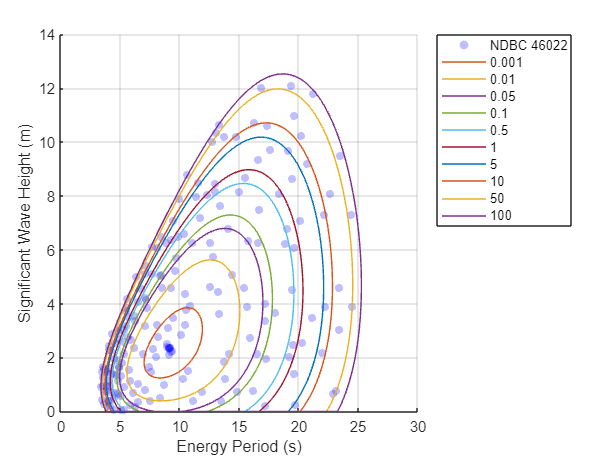

Hm0_contours = zeros(length(levels),1000);
Te_contours = zeros(length(levels),1000);
for p = 1:length(levels)
    contour = environmental_contours(Hm0, Te, dt, levels(p), "PCA", "return_fit",true);
    Hm0_contours(p,:) = contour.contour1;
    Te_contours(p,:) = contour.contour2;
end

plot_environmental_contours(sample_te,sample_hs,Te_contours,Hm0_contours,"x_label",...
    'Energy Period (s)', "y_label",'Significant Wave Height (m)',"data_label",'NDBC 46022',...
    "contour_label",string(levels'));

## 2. Short-Term Extreme Distributions

Many different methods for short-term extremes were adapted from WDRT, and a summary and examples can be found in `short_term_extremes_example.ipynb`. The response quantity of interest is typically related to the WEC itself, e.g. maximum heave displacement, PTO extension, or load on the mooring lines. This requires running a simulation (e.g. WEC-Sim) for each of the 200 ***(H, T)*** sampled sea states.

For the sake of example we will consider the wave elevation as the quantity of interest (can be thought as a proxy for heave motion in this example). Wave elevation time-series for a specific sea state can be created quickly without running any external software.

**NOTE:** The majority of the for loop below is simply creating the synthetic data (wave elevation time series). In a realistic case the variables `time` and `data` describing each time series would be obtained externally, e.g. through simulation software such as WEC-Sim or CFD. For this reason, the details of creating the synthetic data are not presented here, instead assume for each sea state there is time-series data available.

The last lines of the for-loop create the short-term extreme distribution from the time-series using the `loads.extreme.short_term_extreme` function. The short-term period will be 3-hours and we will use 1-hour "simulations" and the Weibull-tail-fitting method to estimate the 3-hour short-term extreme distributions for each of the 200 samples.

For more details on short-term extreme distributions see `short_term_extremes_example.ipynb` and

*[3] Michelén Ströfer, Carlos A., and Ryan Coe. 2015. “Comparison of Methods for Estimating Short-Term Extreme Response of Wave Energy Converters.” In OCEANS 2015 - MTS/IEEE Washington, 1–6. IEEE.*

NOTE: For calculating the `short_term_extreme` of each state, we set the optional argument `output_py` to `true` in order to return the native python output that we can then feed into our long term extreme function. Consequently, we can put arbitrary inputs to the `x` and `method` inputs of the `short_term_extreme` function. 

% create the short-term extreme distribution for each sample sea state
t_st = 3.0 * 60.0 * 60.0;
gamma = 3.3;
t_sim = 1.0 * 60.0 * 60.0;

for i=1:length(sample_hs)
    tp = sample_te(i) / (0.8255 + 0.03852 * gamma - 0.005537 * gamma^2 + 0.0003154 * gamma^3);
    % time & frequency arrays
    df = 1.0 / t_sim;
    T_min = tp / 10.0;  % s
    f_max = 1.0 / T_min;
    Nf = int32(f_max / df) + 1;
    time = linspace(0, t_sim, 2 * Nf + 1);
    f = linspace(0.0, f_max, Nf);
    fprintf("Sea state %g/%g. (Hs, Te) = (%.2f m, %.2f s). Tp = %.2f s\n",i,200,sample_hs(i),sample_te(i),tp);
    % spectrum
    S = jonswap_spectrum(f, tp, sample_hs(i), gamma);
    % 1-hour elevation time-series
    data = surface_elevation(S, time);
    % 3-hour extreme distribution
    ste_all{i} = short_term_extreme(time, data.elevation, t_st, "peaks_weibull_tail_fit", 100, "cdf", "output_py",true);
end

Sea state 1/200. (Hs, Te) = (2.87 m, 10.18 s). Tp = 11.26 s
Sea state 2/200. (Hs, Te) = (3.23 m, 10.46 s). Tp = 11.57 s
Sea state 3/200. (Hs, Te) = (3.78 m, 10.59 s). Tp = 11.72 s
Sea state 4/200. (Hs, Te) = (3.49 m, 9.51 s). Tp = 10.53 s
Sea state 5/200. (Hs, Te) = (3.12 m, 9.07 s). Tp = 10.04 s
Sea state 6/200. (Hs, Te) = (2.53 m, 9.01 s). Tp = 9.97 s
Sea state 7/200. (Hs, Te) = (2.78 m, 8.23 s). Tp = 9.11 s
Sea state 8/200. (Hs, Te) = (2.41 m, 8.94 s). Tp = 9.89 s
Sea state 9/200. (Hs, Te) = (2.32 m, 7.81 s). Tp = 8.64 s
Sea state 10/200. (Hs, Te) = (2.04 m, 8.03 s). Tp = 8.89 s
Sea state 11/200. (Hs, Te) = (1.66 m, 7.45 s). Tp = 8.25 s
Sea state 12/200. (Hs, Te) = (1.48 m, 7.66 s). Tp = 8.48 s
Sea state 13/200. (Hs, Te) = (2.35 m, 9.11 s). Tp = 10.08 s
Sea state 14/200. (Hs, Te) = (2.35 m, 9.12 s). Tp = 10.09 s
Sea state 15/200. (Hs, Te) = (2.11 m, 9.11 s). Tp = 10.08 s
Sea state 16/200. (Hs, Te) = (2.21 m, 9.32 s). Tp = 10.32 s
Sea state 17/200. (Hs, Te) = (2.25 m, 9.37 s). Tp = 1

## 3. Long-Term Extreme Distribution

Finally we integrate the weighted short-term extreme distributions over the entire sea state space to obtain the extreme distribution, assuming a 3-hour sea state coherence. For this we use the `full_seastate_long_term_extreme` function. The integral reduces to a sum over the 200 bins of the weighted short-term extreme distributions.

Similar to the short-term extreme functions, the output of long-term extreme function is a probability distribution. Here, we will look at the survival function and the 100-year return level.The value of the survival function at a given return level (e.g. 100-years) may be calculated using the `return_year_value` function.

t_st_hr = t_st / (60.0 * 60.0);
t_return_yr = 100.0;
probability_of_exceedance = 1 / (t_return_yr * 365.25 * 24 / t_st_hr);
x_t = full_seastate_long_term_extreme(ste_all, sample_weights, 1-probability_of_exceedance, "ppf");
fprintf("100-year elevation: %.3f meters", x_t)

100-year elevation: 10.299 meters

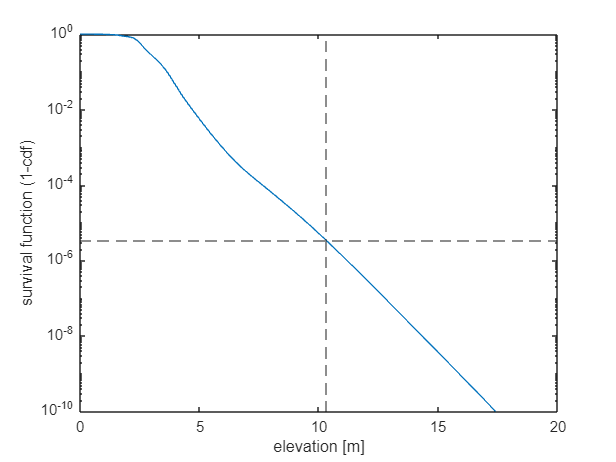

% plot survival function
x = linspace(0, 20, 1000);
lte_sf = full_seastate_long_term_extreme(ste_all, sample_weights, x, "sf");
figure;
semilogy(x, lte_sf);
xlabel('elevation [m]'); ylabel('survival function (1-cdf)'); ylim([1e-10, 1]); xlim([0, x(end)]);
% add 100-year return level to plot
hold on
st_sf = full_seastate_long_term_extreme(ste_all, sample_weights, x_t, "sf");
xline(x_t, '--')
yline(st_sf, '--')